# LQOC Using Black Box Models

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

As seen [earlier](matlab:open('../7. Model_Predictive_Control_Feedback_Version_19Nov2025/L01_StateFeedbackControl_with_Estimator.mlx')), we have developed state feedback controllers based on states estimated using observers that combine measurements with model predictions. We have also seen that to deal with drifting unmeasured disturbances and MPM, the control laws need to be modified using moving state and input targets to achieve offset free control. We had earlier used a linearized model for implementing MPC, however in real applications, such models may not be available and hence we have to use models that are identified from experimental data. In Module 8, we have developed black box state space models starting from input-output data. In this chapter we illustrate how state feedback controller  developed in Module 7 can be modified to work with black-box state space model. 

Learning objectives are: 

- Modify state feedback regulator by introducing moving target states and target inputs for dealing with unmeasured disturbances and model plant mismatch 

## State Feedback Control using Identified State Space Model

 Let us assume that the system dynamics are governed by the ideal discrete time linear model

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_d d\left(k\right)\\
y\left(k\right)=\textrm{Cx}\left(k\right)+v\left(k\right)
\end{array}$   -----------(1)

where $x\in R^n$. 

**Internal Model ** 

We develop LQR using an innovation form of black-box state space model identified from input-output data 

  $\begin{array}{l}
\chi \left(k+1\right)=\tilde{\Phi} \chi \left(k\right)+\tilde{\Gamma} u\left(k\right)+\tilde{L} \;e\left(k\right)\\
y\left(k\right)=\tilde{C} \;\chi \left(k\right)+e\left(k\right)
\end{array}$  ----------(2)

and use $\hat{x} \left(k\right)$ estimated as 

$\begin{array}{l}
\chi \left(k\right)=\tilde{\Phi} \chi \left(k-1\right)+\tilde{\Gamma} u\left(k-1\right)+\tilde{L} \;e\left(k-1\right)\\
e\left(k-1\right)=y\left(k\right)-\tilde{C} \;\chi \left(k\right)
\end{array}$ ------(3)

for initializing the model predictions. The innovation signal, $y\left(k\right)-\tilde{C} \;\chi \left(k\right)$ computed using (3) contains the information about the unmeasured disturbances and model plant mismatch (MPM). Thus the fixed gain state feedback laws of the form $u\left(k\right)=G\chi \left(k\right)$ can be used for unconstrained finite horizon MPC formulation and for the infinite horizon LQOC.  

In the case of finite horizon unconstrained MPC controller, the nominal stability had to be established by finding eigenvalues of $\left(\tilde{\Phi} -\tilde{\Gamma} G_{\textrm{MPC}} \right)$. Using Lyapunov's second method, it was shown that the infinite horizon LQOC guarantees closed loop stability and all eigenvalues of $\left(\tilde{\Phi} -\tilde{\Gamma G_{\infty } } \right)$ are strictly inside the unit circle if the system is reachable.

Note that $\chi \in R^{n_x }$, and, in general, $\;n_x \not= n$.  Thus, MPM is inherent when a such a black-box model is used.  If it is desired to achieve offset free control in the face of unmeasured disturbances or MPM or move the system from the equilibrium point to an arbitrary setpoint, then the state feedback control law has to be further modified. In order to deal with such situations**, **it is necessary to introduce integral action in the controller. As discussed in Module 5, one method to achieve this is to modify the state state feedback control law using time varying target states and target inputs. In Module 5, we have computed target state state and target inputs using ***open loop observer, ***i.e. $L$ equals null matrix. We need to modify the target state computations now to account for the fact that a state estimator given by equation (2) is used as an internal model. The innovation signal, $e\left(k\right)=y\left(k\right)-\tilde{C} \chi \left(k\right)$, contains information about unmeasured disturbances and MPM. Under the assumption that $e\left(k+j\right)=e\left(k\right)\;\textrm{for}\;j>k$, moving equilibrium point of the internal model can be found by solving for

$\chi_s \left(k\right)=\tilde{\Phi} \chi \left(k\right)+\tilde{\Gamma} u_s \left(k\right)+L\;e\left(k\right)$   ------(4)

$y_s \left(k\right)=\tilde{C} \chi_s \left(k\right)+e\left(k\right)$   ------(5)

Eliminating ${\widehat{x} }_s \left(k\right)$ in equation (4) using

 $\chi_s \left(k\right)={\left(I-\tilde{\Phi} \right)}^{-1} \left(\tilde{\Gamma} u_s \left(k\right)+L\;e\left(k\right)\right)$  ----(6)

we arrive at 

$\begin{array}{l}
y_s \left(k\right)=\left(\tilde{C} {\left(I-\tilde{\Phi} \right)}^{-1} \Gamma \right)\;u_s \left(k\right)+\left(I+\tilde{C} {\left(I-\tilde{\Phi} \right)}^{-1} L\right)\;e\left(k\right)\\
\;\;\;\;\;\;\;\;\;\;=\tilde{G\;} u_s \left(k\right)+\tilde{G_e } \;e\left(k\right)
\end{array}$ ------(7)

Setting $y_s \left(k\right)=r\left(k\right)$, when $l=m$, we can derive expression for $u_s \left(k\right)$ as follows 

 $u_s \left(k\right)={\left(\tilde{G} \right)}^{-1} \;\left(r\left(k\right)-\tilde{G_e } \;e\left(k\right)\right)$------(8)

When $u_s \left(k\right)$ computed using (8) is outside the input bounds, or when $l\not= m$, the target state can be computed by solving $u_s \left(k\right)$ can be found by solving the following optimization problem

$\min_{u_s \left(k\right)} \left\lbrace {\left(r\left(k\right)-y_s \left(k\right)\right)}^T \;W_{\textrm{ys}} \left(r\left(k\right)-y_s \left(k\right)\right)\right\rbrace$   ------(9)

subject to,

$y_s \left(k\right)=\tilde{G\;} u_s \left(k\right)+\tilde{G_e } \;e\left(k\right)$ ------(10) 

$u^L \le u_s \left(k\right)\le u^H$ ------ (11)

In either case, $x_s \left(k\right)$ can be found using equation (6). Using target states and target inputs, the control law is modified as follows 

$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Delta u\left(k\right)=-\tilde{G} \Delta x\left(k\right)\\
\Delta x\left(k\right)=x\left(k\right)-x_s \left(k\right)\;\;\textrm{and}\;\;\Delta u\left(k\right)=u\left(k\right)-u_s \;\left(k\right)
\end{array}$   -------(12)

 Thus, the state feedback control law that solves **servo and regulatory problems simultaneously **can be expressed as follows:

$u\left(k\right)=u_s \left(k\right)-\tilde{G} \left\lbrack x\left(k\right)-x_s \left(k\right)\right\rbrack$   ------(13)

## Quadruple Tank System: Simulation Study

In this demo, we will implement the controllers using models directly identified from data.

 
clear all
close all 

global QTank U_k D_k  % Define global variables for quadruple tank 

**Task 1:** Select operating point: **(1) Minimum Phase Operation (2) Non-minimum phase operation. **This will load the parameters specific to the operating point. Let us set the operating point to Minimum Phase first

operating_pt=2; 
if operating_pt==1
load QTank_MinPhase_Model
else
    load QTank_NonMinPhase_Model
end


**Initialize linear model for plant simulation **

% Quadruple tank System: Non-Minimum phase operating point 
phy= QTank.phy 

phy =     0.9404         0    0.0901         0
         0    0.9600         0    0.0606
         0         0    0.9070         0
         0         0         0    0.9381


gam = QTank.gama_u 

gam =     0.1871    0.0144
    0.0069    0.1370
         0    0.2955
    0.2167         0


gam_d = QTank.gama_d 

gam_d =     0.0026
    0.0023
    0.0544
    0.0727


C_mat = QTank.C_mat   % Levels h(1) and h(2) are measured in quadruple tank 

C_mat =     0.5000         0         0         0
         0    0.5000         0         0


[n_op, nx ] = size(C_mat)  ;
[n_st, n_ip] = size(gam) ;
[nx, n_d] = size(gam_d) ;

Q_mat = QTank.Q_mat ;
R_mat = QTank.R_mat ;

**Task 2: **Initialize internal model for LQOC as black box innovation form of state space model(with observer) or Blackbox OE model or grey box OE model or grey box observer, which we have created in module 8. We have the following models which can be loaded in the workspace. Select any model and run the simulations.

model_type=4 

model_type = 4

if operating_pt==1
    if (model_type==1)
        load QTank_MP_GreyBox_OE_SS.mat
    elseif (model_type==2)
        load QTank_MP_GreyBox_INV_SS.mat
    elseif (model_type == 3)
        load QTank_MP_BlackBox_OE_SS.mat
    else
        load QTank_MP_BlackBox_INV_SS_6.mat
    end
else
    if model_type==1
        load QTank_NMP_GreyBox_OE_SS.mat
    elseif model_type==2
        load QTank_NMP_GreyBox_INV_SS.mat
    elseif model_type==3
        load QTank_NMP_BlackBox_OE_SS.mat
    else
        load QTank_NMP_BlackBox_INV_SS_6.mat
    end
end

**Initialize internal model for LQOC**

lqr.phy=idmod.phy;
lqr.gam=idmod.gam;
lqr.C_mat=idmod.C;
[lqr.n_st, lqr.n_ip] = size(lqr.gam) ;
lqr.n_op = n_op ;
lqr.L_mat=idmod.L_mat;

lqr.phy

ans =     0.9734    0.0064   -0.0005    0.0126   -0.0056    0.0339
    0.0253    1.0078   -0.0515    0.0039   -0.0131    0.0078
   -0.0056    0.0815    0.9159   -0.0173   -0.1302   -0.0517
   -0.0811    0.0232   -0.0370    0.9164    0.0216   -0.0949
   -0.0115    0.0084    0.0714   -0.0126    0.5960   -0.7659
    0.0121   -0.0129   -0.0463    0.0467   -0.0165    0.0406


lqr.gam

ans =     0.0018    0.0015
   -0.0026    0.0011
   -0.0065    0.0120
    0.0022    0.0125
   -0.0037    0.0156
   -0.0022    0.0105


lqr.C_mat

ans =    29.7406  -10.2586   -1.8375   -0.7506   -0.6452   -0.0514
   28.2549   10.2330    2.0203   -0.9034    0.5250    0.0841


lqr.L_mat

ans =     0.0039    0.0016
   -0.0037    0.0031
    0.0113    0.0081
    0.0337    0.0117
   -0.0001    0.0165
   -0.0126    0.0148


lqr.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
lqr.u_L = [0 0]' - QTank.Us ;  

**Task 3:**Set the tuning matrices of the controller  as  

$W_y =\left\lbrack \begin{array}{cc}
\alpha_1  & 0\\
0 & \alpha_2 
\end{array}\right\rbrack$,  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$, $W_{x}=[C^{T}W_{y}C]   ;  $

Using these tuning parameters and the model obtained from system identification, controller gain is obtained using [**dlqr**](https://in.mathworks.com/help/control/ref/lti.dlqr.html) command in MATLAB

beta(1)=1;
beta(2)=1;
alpha(1)=5;
alpha(2)=2;
% LQOC tuning matrices and controller design 
disp('Input weighting matrix')

Input weighting matrix


lqr.Wu = diag(beta) ;
disp('Output weighting matrix')

Output weighting matrix


lqr.Wy =diag(alpha) ; 
Wx_y = lqr.C_mat' * lqr.Wy * lqr.C_mat ;
[lqr.G_inf,S_inf, Eig_CL_con] = dlqr(lqr.phy, lqr.gam, Wx_y, lqr.Wu, zeros(lqr.n_st,lqr.n_ip)) ;
disp('Controller gain is')

Controller gain is


lqr.G_inf

ans =    52.0269   -3.2886   -6.4599    3.0647    1.3920    1.0819
   30.5881  -12.1992    7.0482   -0.1048   -2.2195    2.3046


disp('Maximum Absolute Closed loop Eigen value')

Maximum Absolute Closed loop Eigen value


rho_con = max(abs(Eig_CL_con)) 

rho_con = 0.9547

The gains $\tilde{G\;} \;\textrm{and}\;\tilde{G_e } \;$are then computed using equation (7), which are then used in the computation of target states and target inputs.

% Gains used in the computation of target states and target inputs.
lqr.Gain_ss = lqr.C_mat * inv(eye(lqr.n_st)-lqr.phy)*lqr.gam ; 
lqr.Gain_ss_inv =inv(lqr.Gain_ss) ;
lqr.inv_mat = inv(eye(lqr.n_st) - lqr.phy) ;
lqr.Gain_e = eye(lqr.n_op) + lqr.C_mat * inv(eye(lqr.n_st)-lqr.phy)* lqr.L_mat ;

** Disturbance input **

A time varying disturbance input signal is generated such that initially it is set to zero for $k<0$. It is changed such that $200\le k<400$ it 's magnitude is 0.5 and for $k>400$ it is 0.25

We now add the innovation filter and observe the closed loop behaviour of the controller.

**Task 4: **Set **innovation_filter_on**  flag to 1 and set the **alfa_e** value to 0.98. (alfa_e value can be set to 0 to see effect of noise on u(k).) Innovation filter is designed using this parameter.

innovation_filter_on = 1 ;

if (innovation_filter_on == 1)
    alfa_e =0.98;  % Set this value to 0 to see effect of noise on u(k)
    lqr.phy_e = alfa_e * eye(n_op) ;  % Innovation filter
else
    alfa_e = 0 ;
end

**Task 5: **Change setpoint filter parameter between 0.9 and 0.99. Setting it equal to zero will eliminate innovation filter. 

beta_r =0.9;  % Set this value to 0 see effect of step change in rk on u(k) 
lqr.phy_r = beta_r * eye(n_op) ; % 

 Generate state and measurement noise sequences 

**Initialization for Process Simulation **

N = 651 ;   % Set Simulation time 

lqr.xkhat = zeros(lqr.n_st,N);  % LQR internal model states 
lqr.xs_k = zeros(lqr.n_st,N);   % Target state 
lqr.us_k = zeros(n_ip,N) ;        % Target input 
lqr.ek = zeros(n_op,N) ;
lqr.ek_f = zeros(n_op,N) ;
lqr.rk_f = zeros(n_op,N);     % Setpoint filter parameters

xk = zeros(n_st,N);
xk(:,1) =[1 -1 1 -1]';
uk = zeros(n_ip,N) ;
yk = zeros(n_op,N) ;
yk(:,1) = C_mat * xk(:,1) ;
dk = zeros(1,N) ;

**Task 6:** Set the value of Noise_ON to 1 to introduce white noise disturbances in the states and measurements.

Noise_ON=1% Set this value to 1 to introduce white noise disturbances  

Noise_ON = 1

wk = mvnrnd(zeros(n_d,1), Q_mat, N) ;
wk = Noise_ON * wk' ;
vk = mvnrnd(zeros(n_op,1), R_mat, N) ;
vk = Noise_ON * vk' ;

** Disturbance input **

A time varying disturbance input signal is generated such that initially it is set to zero for $k<0$. It is changed such that $200\le k<400$ it 's magnitude is 0.5 and for $k>400$ it is 0.25

for k = 1:N
    if ( k < 200 )
        dk(k) = 0 ;
    elseif (k >= 200 ) && (k < 400)
        dk(k) = 0.5 ;  % Introduce disturbance change at k = 200
    else
        dk(k) = 0.25  ;  % Introduce another disturbance change at k = 400
    end
end
dk = dk + [zeros(1, 200) wk(201:end) ] ; 
rk = zeros(n_op,1) ;

**Task 7: **Select Plant_Sim as Linear for simulating Q Tank process using linear discrete model.

Plant_Sim =0  ;

for k = 1:N-1
    kT(k) = (k-1);

    % Implement LQOC at instant k  
    [ uk(:,k), lqr] = LQOC( lqr, rk, yk(:,k), k ) ;
   
     % Quadruple tank Plant Simulation from k to k+1

    if (Plant_Sim )
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
    else
        U_k = QTank.Us + uk(:,k) ;  
        D_k =  QTank.Ds + dk(k)  ;
        % Nonlinear plant simulation
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;  
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
    yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1);  %Measurement with noise 

 end
uk(:,N) = uk(:,N-1) ;
lqr.ek(:,N) = lqr.ek(:,N-1) ;
lqr.xs_k(:,N) = lqr.xs_k(:,N-1) ;
lqr.us_k(:,N) = lqr.us_k(:,N-1) ; 
kT(N) = N-1 ; 


The following function implements LQOC controller with the ad-hoc way of handling the input bound constraints. 

% Linear Quadratic Optimal Control Law implementation 

function [uk_LQR, lqr]  = LQOC( lqr, rk, yk, k ) 

     % Setpoint filtering 
     lqr.rk_f(:,k+1) = lqr.phy_r * lqr.rk_f(:,k) + (eye(lqr.n_op) - lqr.phy_r) * rk   ; 

     % Controller implementation at instant k 
     % Innovation/ MPM signal filtering 
     lqr.ek(:,k) = yk - lqr.C_mat * lqr.xkhat(:,k) ;  
     lqr.ek_f(:,k+1) = lqr.phy_e * lqr.ek_f(:,k) + (eye(lqr.n_op) - lqr.phy_e) * lqr.ek(:,k) ; 

     % Target State Computation 
     lqr.us_k(:,k) =  lqr.Gain_ss_inv * ( lqr.rk_f(:,k+1) - lqr.Gain_e * lqr.ek_f(:,k))  ;
     lqr.xs_k(:,k) = lqr.inv_mat * ( lqr.gam * lqr.us_k(:,k) + lqr.L_mat * lqr.ek_f(:,k))  ;

    % Control law computations 
    uk_LQR = lqr.us_k(:,k) - lqr.G_inf * (lqr.xkhat(:,k) - lqr.xs_k(:,k)) ;

    % Impose uk bound constraints
    uk_clipped = uk_bound_constraints( uk_LQR,  lqr.u_L, lqr.u_H ) ;
    uk_LQR = uk_clipped ;

    % Update the internal model state using the updated uk 
    lqr.xkhat(:,k+1) = lqr.phy * lqr.xkhat(:,k) + lqr.gam * uk_LQR + lqr.L_mat * lqr.ek(:,k) ;
end

% Function to impose input bounds

function uk_clipped = uk_bound_constraints( u_k, u_L, u_H )

% Ad-hoc implementation of bound constraints

uk_clipped = u_k ; 

if ( u_k(1) <= u_L(1) )   % Impose input constraints on uk(1)
    uk_clipped(1) = u_L(1) ;
elseif ( u_k(1) >= u_H(1) )
    uk_clipped(1) = u_H(1) ;
end
if ( u_k(2) <= u_L(2) ) % Impose output constraints on uk(2)
    uk_clipped(2) = u_L(2) ;
elseif ( u_k(2) >= u_H(2) )
    uk_clipped(2) = u_H(2) ;
end
end

** Display simulation results**

Set_Graphics_Parameters

Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  Rk_f = lqr.rk_f + C_mat * QTank.Xs ;
u_limit = [lqr.u_L(1)*ones(N,1) lqr.u_H(1)*ones(N,1)]  ;


**Controlled output profiles **

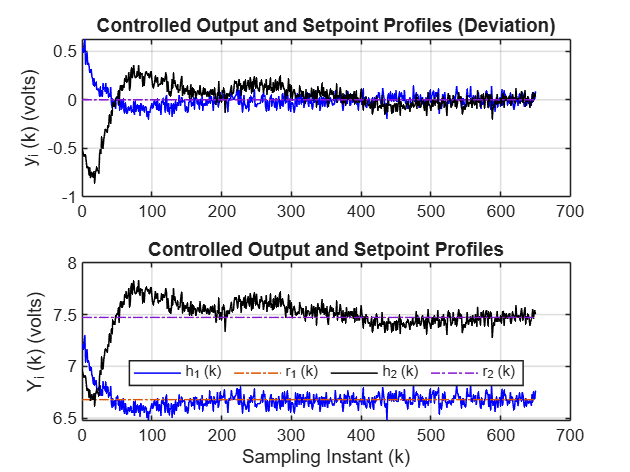

figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, lqr.rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, lqr.rk_f(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k) (volts)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Rk_f(1,:), '-.', kT, Yk(2,:), 'k', kT, Rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k) (volts)')
legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

**Manipulated input profiles**

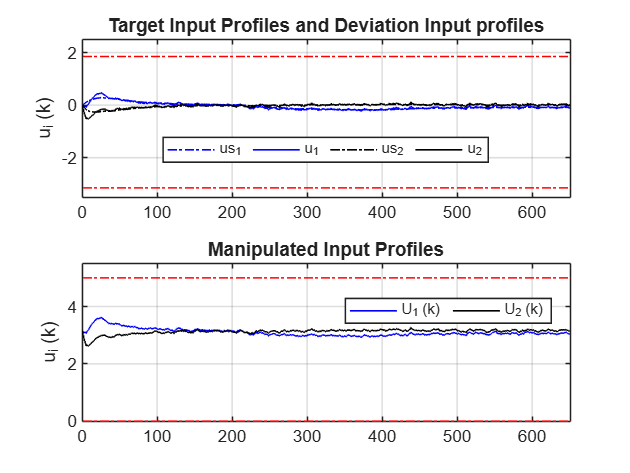

figure, subplot(211), stairs(kT, lqr.us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)
stairs(kT, lqr.us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)
axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

** Disturbance input and Model Plant Mismatch profiles **

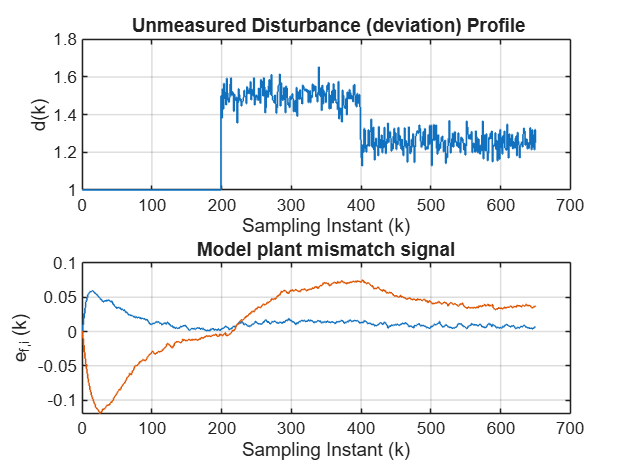

figure, subplot(211), stairs( kT, Dk,'LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)')
title(' Unmeasured Disturbance (deviation) Profile')
subplot(212), stairs( kT, lqr.ek_f','LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('e_f_,_i (k)')
title('Model plant mismatch signal')

**System State profiles and LQR internal model profiles **

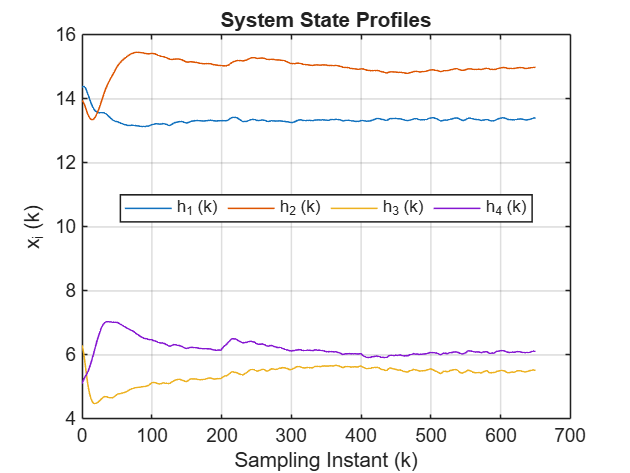

figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('h_1 (k)', 'h_2 (k)', 'h_3 (k)', 'h_4 (k)', 'Orientation','horizontal','Location','Best')
title('System State Profiles')

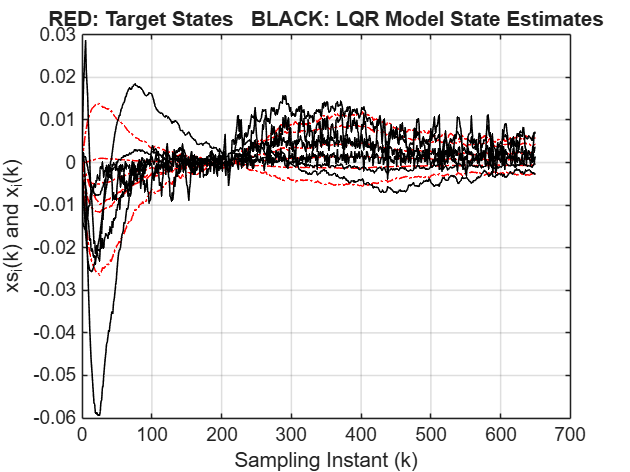

figure, plot(kT, lqr.xs_k, '-.r', kT, lqr.xkhat, 'k'), grid
title('RED: Target States   BLACK: LQR Model State Estimates')
xlabel('Sampling Instant (k)'), ylabel('xs_i(k) and x_i(k)')

We can see that the LQOC developed using a black-box state space model is capable of tracking the outputs and reject the unmeasured disturbances. 

**Task 8**:   Change $\alpha_e$ from 0 to maximum value and observe the behavior of manipulated inputs? How does the sensitivity of manipulated inputs to noise change when $\alpha_e$ is changed? 

**Task 9: **Now change the type of identified model from Output Error to Grey-box or Black-box observer. Do you notice differences in handling of  disturbance input when we change OE to observer structure? Running simulations by switching off noise can help see the differences. 

**Task 10**: Let us change the operating point to Non-minimum phase and observe the results. Does the performance remain same? Do you need to  re-tune the controller?

## Summary and Conclusions 

In this lesson, a state feedback controller has been implemented using black-box state space observers identified from input-output data. The states of the model are artificial mathematical constructs and have no physical interpretation. In spite of the MPM is inherent when such a model is employed from controller synthesis, the LQOC developed using this model is able to reject unmeasured disturbances and achieve desired setpoint transitions when integral action is introduced through target state and target input calculations. Moreover, the closed loop performance is qualitatively similar to the performance obtained using linearized mechanistic model. 